# Homework II - Spectral Clustering - Ghezzi Paradiso

clear variables

## Parameter setting

k = k-nearest neighborhood similarity graph parameter (user chosen)

epsilon = minimum similarity value for a connection to take place between two data points in the similarity matrix (fixed)

maxIter = maximum number of iterations for inverse power method

relTol = relative tolerance for inverse power method

%% Parameters setting
fprintf("enter a value for k: either 10, 20 or 40 (default is 10)\n")

enter a value for k: either 10, 20 or 40 (default is 10)


prompt1 = "enter k: either 10, 20 or 40 (default is 10) \n";
k = str2double(input(prompt1,"s"));
if isnan(k)
    k = 10;
end
epsilon = eps;
maxIter = 3000;
relTol = 1e-9;

## Data loading

Loading the user specified dataset

%% Loading data
fprintf("enter a dataset: either Circle.mat or Spiral.mat (default is Circle.mat)\n")

enter a dataset: either Circle.mat or Spiral.mat (default is Circle.mat)


prompt2 = "enter a dataset: either Circle.mat or Spiral.mat (default is Circle.mat) \n";
datasetName = input(prompt2,"s");
if isempty(datasetName)
    datasetName = 'Circle.mat';
end

switch datasetName
    case 'Circle.mat'
        data = 'Circle';
    case 'Spiral.mat'
        data ='Spiral';
end

X_wl=load(datasetName);

## Matrix initialization

Initializing the matrices that will be necessary for the computations

n=max(size(X_wl.X)); % matrix dimension
S=zeros(n,n); % similarity matrix
W=zeros(n,n); % weight matrix
D=zeros(n,n); % degree matrix
L=zeros(n,n); % laplacian matrix
d = zeros(n,1); % diagonal of D

% saving labels of Spiral.mat dataset to make comparisons with our
% clustering results
if strcmp(data, 'Spiral')
    labels = X_wl.X(:, 3);
end

% since the loaded X_wl is a struct datatype, we save its content into a matrix X for better indexing 
X=X_wl.X(:, 1:2);

## 1. K-nearest neighborhood similarity graph G and adjacency matrix W

Creating the similarity matrix S

% Similarity matrix S
for i=1:n
    % since S(i,j)=S(j,i) we can compute just the upper triangular part of S and extend it to the full matrix
    for j=i+1:n 
            S(i,j)= expm(-norm(X(i,:) - X(j,:))^2./2);
            % checking minimum similarity value
            if S(i,j)<epsilon 
                S(i,j)=0;
            end
            S(j,i)=S(i,j); % making the matrix symmetric
    end
end

Finding the k-nearest neighbours for every point

% k highest values of each row of S and their indeces
[K,I]=maxk(S,k,2);

Generating the adjacency matrix W

% Adjacency matrix W
for i=1:n
    % for every point take only the k-nearest neighbours specified by I
    for j=1:k
        W(i,I(i,j))=K(i,j);
    end
end

To make W symmetric we adopt the following rule: 

i and j are neighbors if i is a k-neighbor of j OR j is a k-neighbor of i

% symmetrising W
for i=1:n
    for j=1:n
        m=max(W(i,j),W(j,i));
        W(i,j)=m;
        W(j,i)=m;
    end
    d(i)=sum(W(i,:)); % saving element D(i,i) of the degree matrix
end

Creating the k-nearest neighbours similarity graph G

% Similarity graph
G=graph(W);

## 2. Degree matrix D and Laplacian matrix L

Constructing the degree matrix D and the Laplacian matrix L = D − W, storing them in sparse format

% Degree matrix 
D = diag(d); 
D = sparse(D);
W = sparse(W);
% Laplacian matrix
L = D - W;

## 3. Number of connected components of G

Obtaining the number of connected components of the graph G

number_conn_comp=max(conncomp(G)); % 2 connected components <--> 2 null eigenvalues

## 4. Some small eigenvalues of L and choice of the number of clusters M

Computing the m smallest eigenvalues of L using the self-implemented function compute_m_smallest_eigenvalues()

m=10;
% compute m smallest eigenvalues
[eigenvalues_L, ~] = compute_m_smallest_eigenvalues(L,m,'no', maxIter, relTol);

Plotting the m smallest eigenvalues to decide a suitable number of clusters to select M

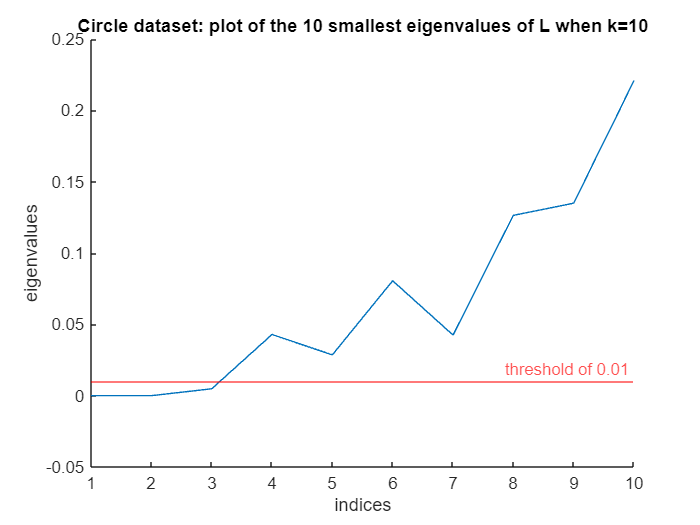

% to decide how many clusters to select, let's plot the smallest
% eigenvalues together with a horizontal line defining a threshold
figure;
hold on;
plot(1:m, eigenvalues_L);
xlabel('indices');
ylabel('eigenvalues');
switch data
    case 'Spiral'
        yline(0.01, 'red', 'threshold of 0.01');
    case 'Circle'
        switch k
            case 10
                yline(0.01, 'red', 'threshold of 0.01');
            case 20
                yline(0.1, 'red', 'threshold of 0.1');
            case 40
                yline(0.8, 'red', 'threshold of 0.8');
        end
end
title(sprintf('%s dataset: plot of the %d smallest eigenvalues of L when k=%d',data, m, k));
hold off;

We decide to take M = 3

% number of clusters
M = 3;

## 5. M eigenvectors of the smallest eigenvalues of L and matrix U

Computation of M eigenvectors corresponding to the M smallest eigenvalues of L, using the self-implemented function compute_m_smallest_eigenvalues() that combines Inverse power method for eigenvalues and Deflation method. 

[M_eigenvalues_L, M_eigenvectors_L] = compute_m_smallest_eigenvalues(L,M,'yes', maxIter, relTol);

Storing the eigenvectors as columns of the nxM matrix U 

U = M_eigenvectors_L;

## 6. Spectral clustering

Performing spectral clustering by applying kmeans algorithm to the n rows of U and storing the index of the cluster to which each point is assigned 

clusters= kmeans(U, M);

## 7. Assignment of original points to clusters

Assigning the original points of the dataset to the same cluster as their corresponding row in U

% dictionary mapping each key (cluster) to the points it contains
Clusters_dict = containers.Map('KeyType', 'int32', 'ValueType', 'any');
for i=1:M
    indices = find(clusters == i);
    Clust_i = zeros(size(indices, 1), 2);
    for j=1:size(indices, 1)
        Clust_i(j, :) = X(indices(j), :);
    end
    Clusters_dict(i) = Clust_i;
end

## 8. Plot of the clusters of points with different colors

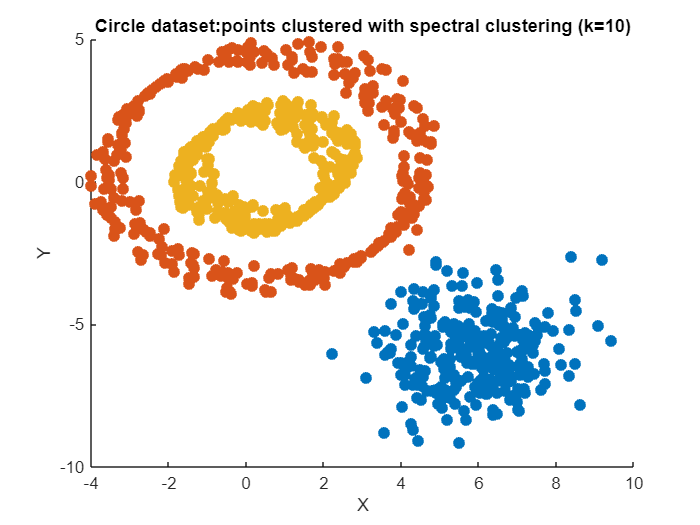

% define M colors
colors = lines(M);
% Plot points
figure;
hold on;
for i = 1:M
    points_clusti = Clusters_dict(i);
    scatter(points_clusti(:, 1),points_clusti(:, 2), 50, colors(i, :), 'filled');
end
xlabel('X');
ylabel('Y');
title(sprintf('%s dataset:points clustered with spectral clustering (k=%d)', data, k));
hold off;

In the case of the Spiral dataset, before plotting the clusters of points obtained using other clustering methods, let us plot the points colored depending on their correct label (retreived from the 3rd column of the dataset)

if  strcmp(data, 'Spiral')
    figure;
    hold on;
    colors_labels = lines(length(unique(labels)));
    for i = 1:length(unique(labels))
        labels_idx = labels == i;
        scatter(X(labels_idx, 1), X(labels_idx, 2), 50, colors_labels(i, :), 'filled');
    end
    % Add labels and legend
    xlabel('X');
    ylabel('Y');
    title('Spiral datatset:points clustered with the original labels');
    hold off;
end

## 9. Clustering with other clustering methods and results comparison

Clustering the data points using different clustering methods (that require to specify a number of clusters) and comparing the results with those obtained using the self-implemented spectral clustering

#### K means

Performing K means algorithm with K = M = 3 clusters on the original points and plotting the resulting clusters with different colors

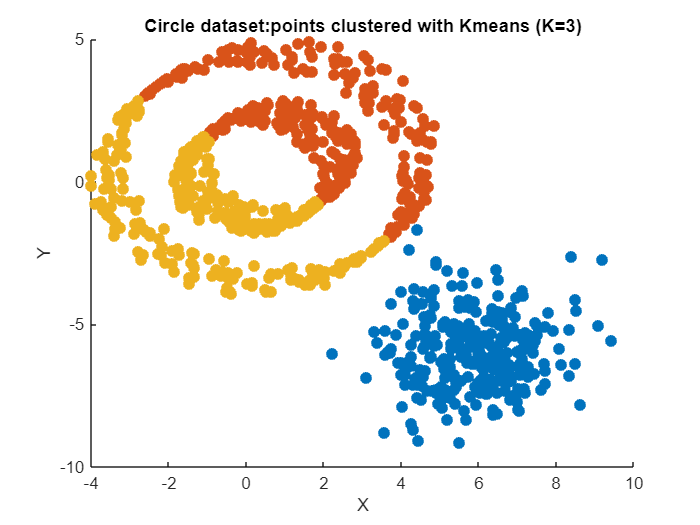

%% kmeans
clusters_km = kmeans(X, M);
figure;
hold on;
for i = 1:M
    clusterIdx_km = clusters_km == i;
    scatter(X(clusterIdx_km, 1), X(clusterIdx_km, 2), 50, colors(i, :), 'filled');
end
xlabel('X');
ylabel('Y');
title(sprintf('%s dataset:points clustered with Kmeans (K=%d)', data, M));
hold off;

#### K medoids

Performing K medoids algorithm with K = M = 3 clusters on the original points and plotting the resulting clusters with different colors

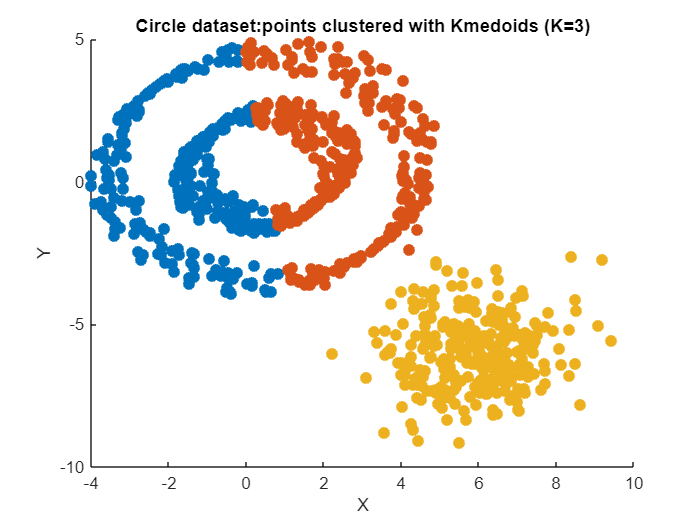

%% kmedoids
clusters_kmed = kmedoids(X, M);
figure;
hold on;
for i = 1:M
    clusterIdx_kmed = clusters_kmed == i; 
    scatter(X(clusterIdx_kmed, 1), X(clusterIdx_kmed, 2), 50, colors(i, :), 'filled');
end
xlabel('X');
ylabel('Y');
title(sprintf('%s dataset:points clustered with Kmedoids (K=%d)', data, M));
hold off;

#### Matlab spectral clustering on the original dataset

Performing spectral clustering algorithm with K = M = 3 clusters on the original points and plotting the resulting clusters with different colors

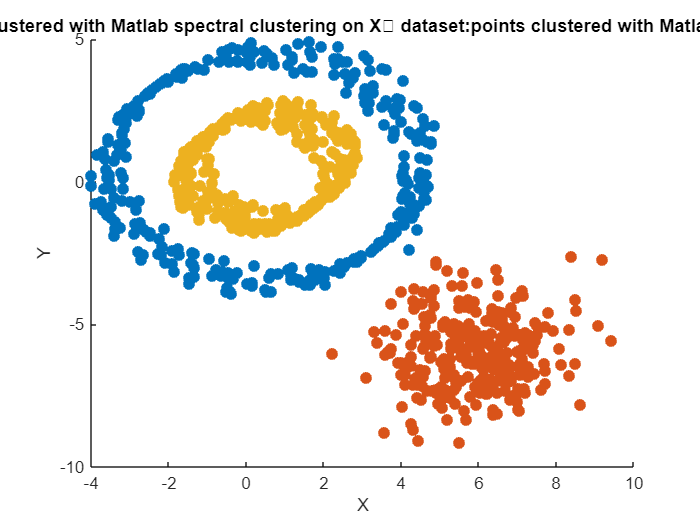

%% spectral clustering on X
clusters_sc_X = spectralcluster(X, M);
figure;
hold on;
for i = 1:M
    clustersIdx_sc = clusters_sc_X == i; 
    scatter(X(clustersIdx_sc, 1), X(clustersIdx_sc, 2), 50, colors(i, :), 'filled');
end
xlabel('X');
ylabel('Y');
title(sprintf('%s dataset:points clustered with Matlab spectral clustering on X', data, M));
hold off;

#### Matlab spectral clustering on the adjacency matrix of G

Performing spectral clustering algorithm with K = M = 3 clusters on the adjacency matrix of the similarity graph G (obtained with the matlab command) and plotting the resulting clusters with different colors

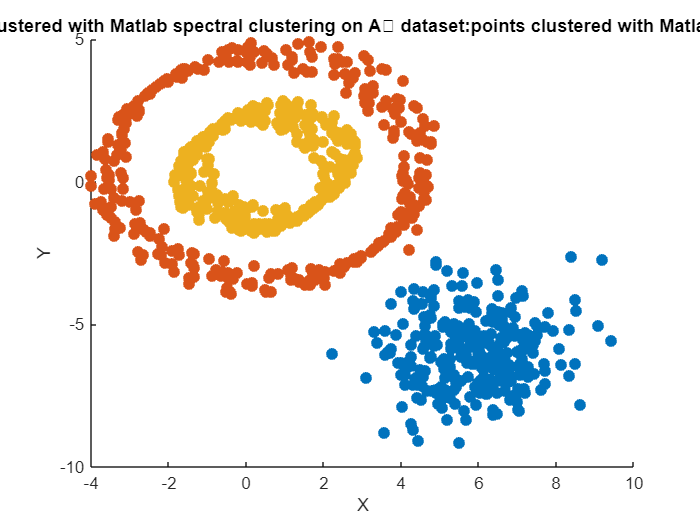

%% spectral clustering on the adjacency matrix A 
A = adjacency(G);
clusters_sc_A = spectralcluster(A, M, 'Distance','precomputed');
figure;
hold on;
for i = 1:M
    clustersIdx_sc = clusters_sc_A == i;
    scatter(X(clustersIdx_sc, 1), X(clustersIdx_sc, 2), 50, colors(i, :), 'filled');
end
xlabel('X');
ylabel('Y');
title(sprintf('%s dataset:points clustered with Matlab spectral clustering on A', data, M));
hold off;

## 10. Try with M>3

Repeating the computations and performing spectral clustering for larger values of M (user specified)

% user specified number of clusters (default is 5)
% fprintf("enter a value for M \n")
prompt3 = "enter M>3: \n";
M2 = str2double(input(prompt3,"s"));
if isnan(M2)
    M2 = 5;
end
% computing eigenvalues and eigenvectors
[M2_eigenvalues_L, M2_eigenvectors_L] = compute_m_smallest_eigenvalues(L,M2,'yes', maxIter, relTol);

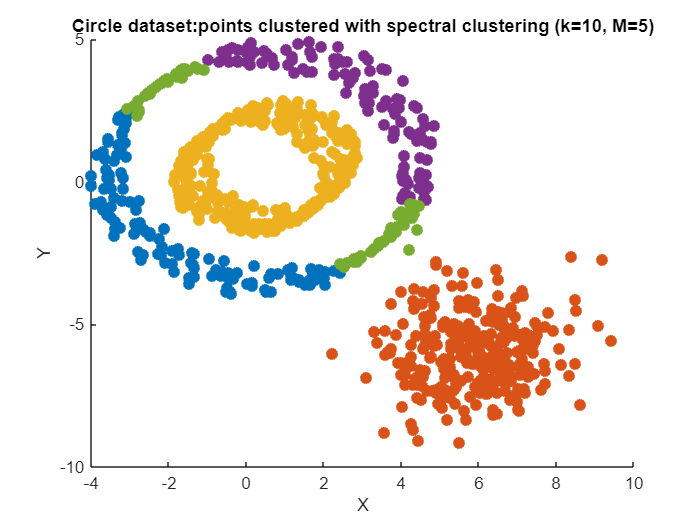

U2 = M2_eigenvectors_L; 
% performing spectral clustering
clusters2= kmeans(U2, M2);
% assigning clusters to the original points
Clusters_dict2 = containers.Map('KeyType', 'int32', 'ValueType', 'any');
for i=1:M2
    indices = find(clusters2 == i);
    Clust_i = zeros(size(indices, 1), 2);
    for j=1:size(indices, 1)
        %k = each element of indices
        Clust_i(j, :) = X(indices(j), :);
    end
    Clusters_dict2(i) = Clust_i;
end
% plotting the clusters of points with different colors
colors2 = lines(M2);
% Plot points
figure;
hold on;
for i = 1:M2
    points_clusti = Clusters_dict2(i);
    scatter(points_clusti(:, 1),points_clusti(:, 2), 50, colors2(i, :), 'filled');
end
xlabel('X');
ylabel('Y');
title(sprintf('%s dataset:points clustered with spectral clustering (k=%d, M=%d)', data, k, M2));
hold off;

## 11. Spectral clustering on the normalized laplacian matrix Lsym

D_inv=zeros(n,n); %inverse of the degree matrix
d_inv=zeros(n,1); %inverse of vector d

% definition of the normalized symmetric Laplacian matrix
d_inv = 1./d; 
%NB: the inverse of a diagonal matrix 
%is a diagonal matrix having inverted diagonal elements
D_inv = diag(d_inv);
L_sym = eye(n,n) - D_inv^(1/2) * W * D_inv^(1/2);

% same procedure of spectral clustering on L_sym
prompt3 = "enter M for L_sym: \n";
Msym = str2double(input(prompt3,"s"));
if isnan(Msym)
    Msym = 3;
end
% computing eigenvalues and eigenvectors
[Msym_eigenvalues_L, Msym_eigenvectors_L] = compute_m_smallest_eigenvalues(L_sym,Msym,'yes', maxIter, relTol);

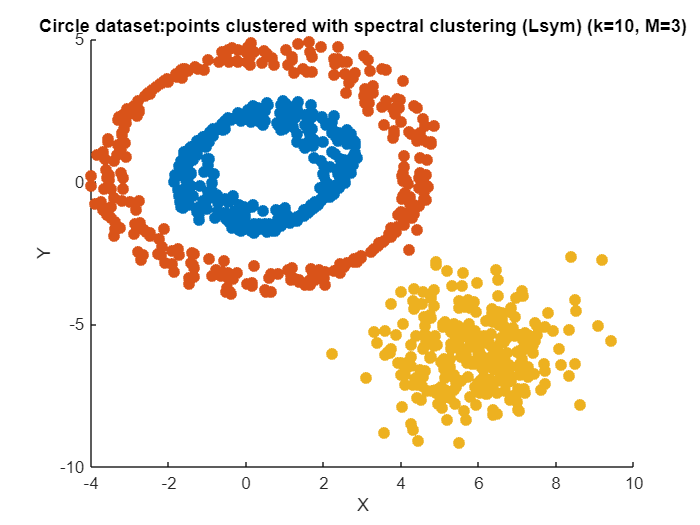

Usym = Msym_eigenvectors_L; 
% performing spectral clustering
clusters_sym= kmeans(Usym, Msym);
% assigning clusters to the original points
Clusters_dict_sym = containers.Map('KeyType', 'int32', 'ValueType', 'any');
for i=1:Msym
    indices = find(clusters_sym == i);
    Clust_i = zeros(size(indices, 1), 2);
    for j=1:size(indices, 1)
        %k = each element of indices
        Clust_i(j, :) = X(indices(j), :);
    end
    Clusters_dict_sym(i) = Clust_i;
end
% plotting the clusters of points with different colors
colors_sym = lines(Msym);
% Plot points
figure;
hold on;
for i = 1:Msym
    points_clusti = Clusters_dict_sym(i);
    scatter(points_clusti(:, 1),points_clusti(:, 2), 50, colors_sym(i, :), 'filled');
end
xlabel('X');
ylabel('Y');
title(sprintf('%s dataset:points clustered with spectral clustering (Lsym) (k=%d, M=%d)', data, k, Msym));
hold off;